# HW03

## Problem 1:

relative change in total energy is very small.

energy plots show that the sum of potential and kinetic energies doesn't change with time and its equal to the total energy. 

Initial conditions doesn't change phase diagram since its oscillatory motion and its always an ellipse. 

If $\theta_0 > 0 \  , \  \dot{\theta}_0=0 $ then motion is clockwise. 

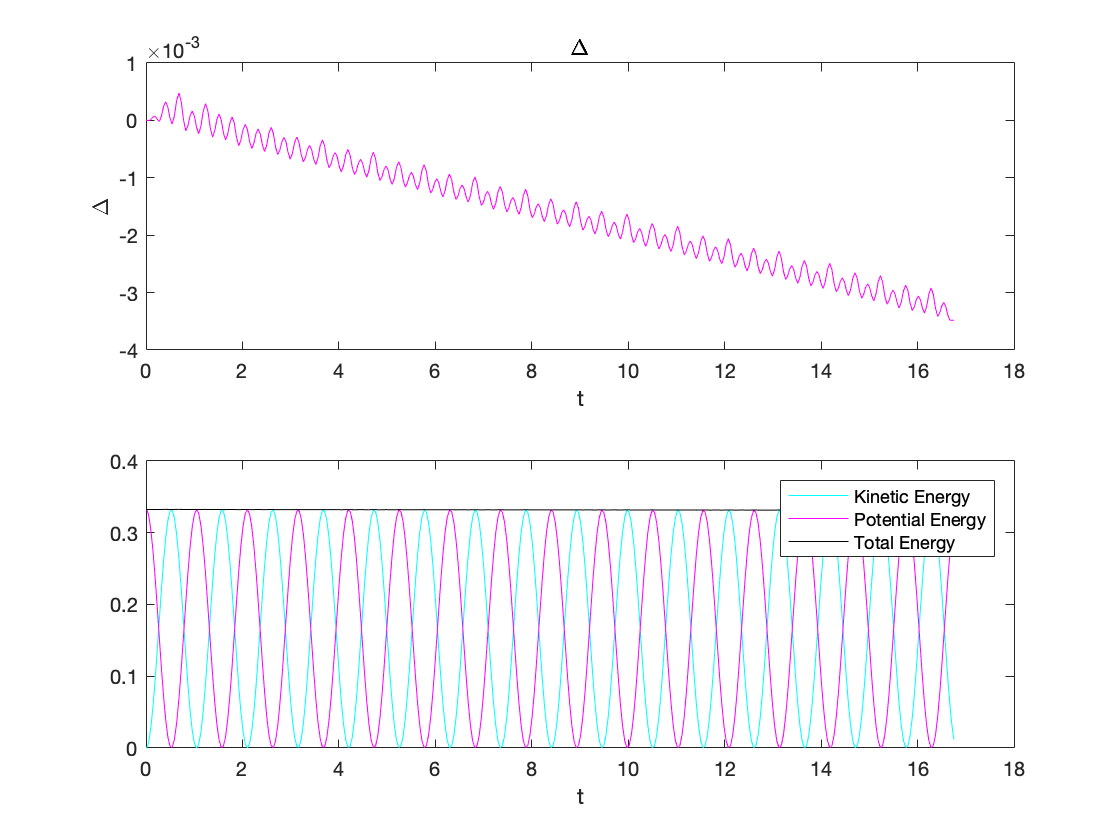

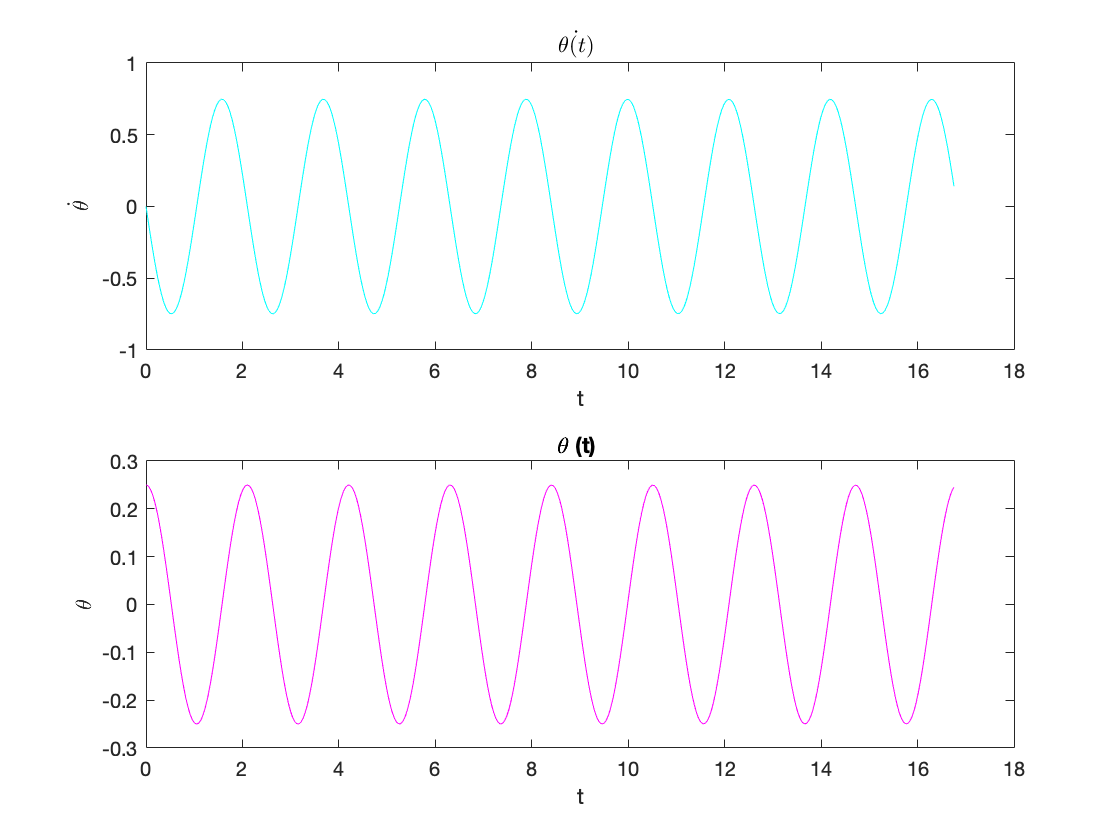

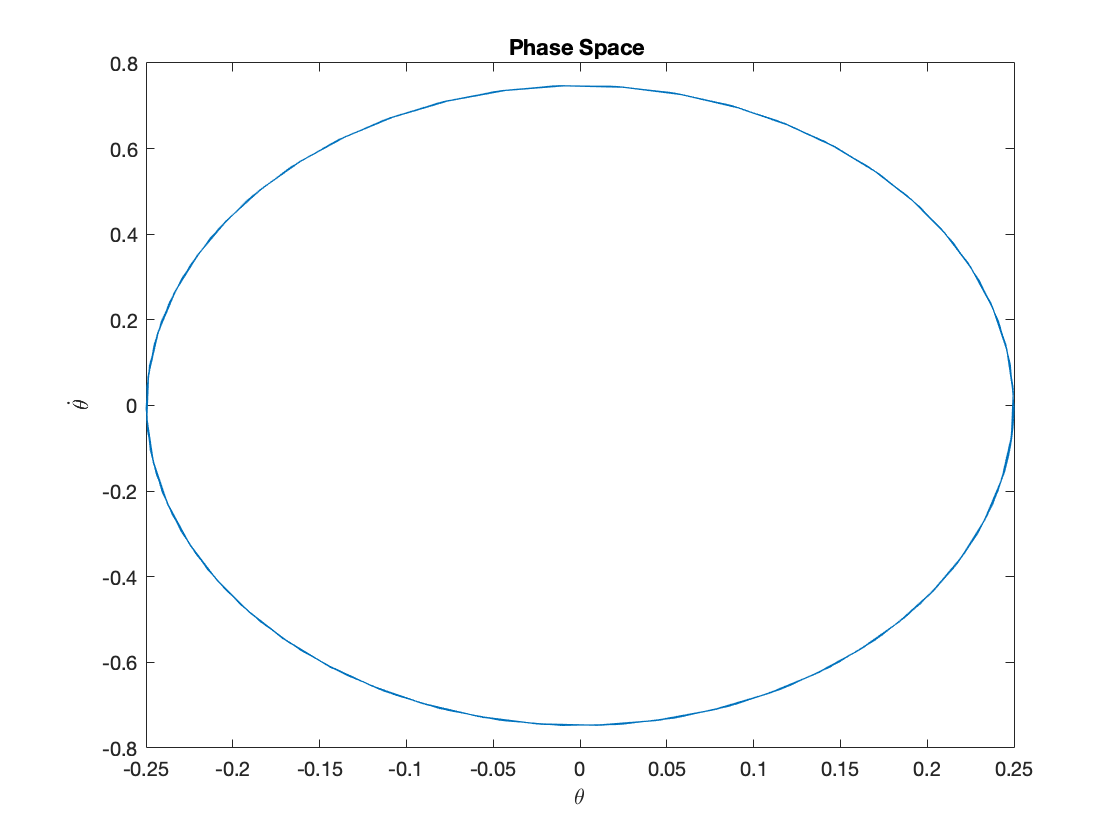

pendulum(1.09,0.25,0,1);

## Problem 2.

**Part a)**

**If you run the pendulum function with large initial angle and look at the function delta which represents the deviation of energy from its initial value, you will see that function delta is very small throughout one complete cycle. **

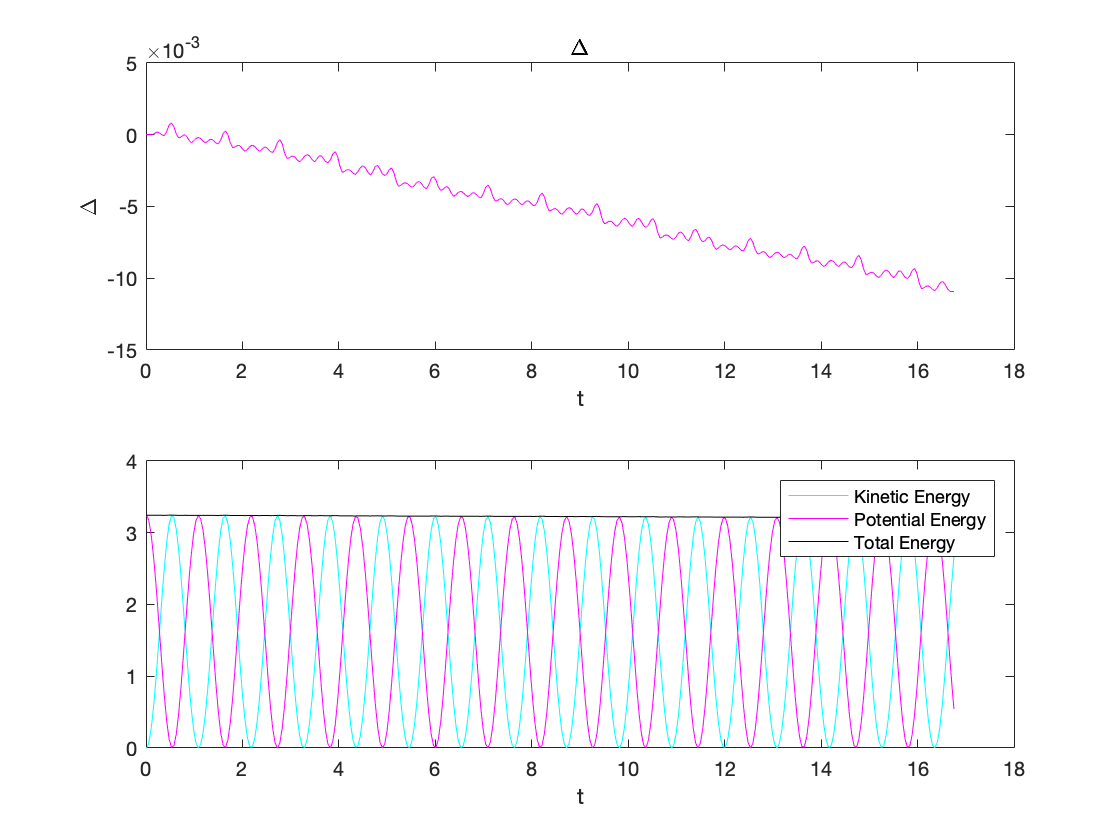

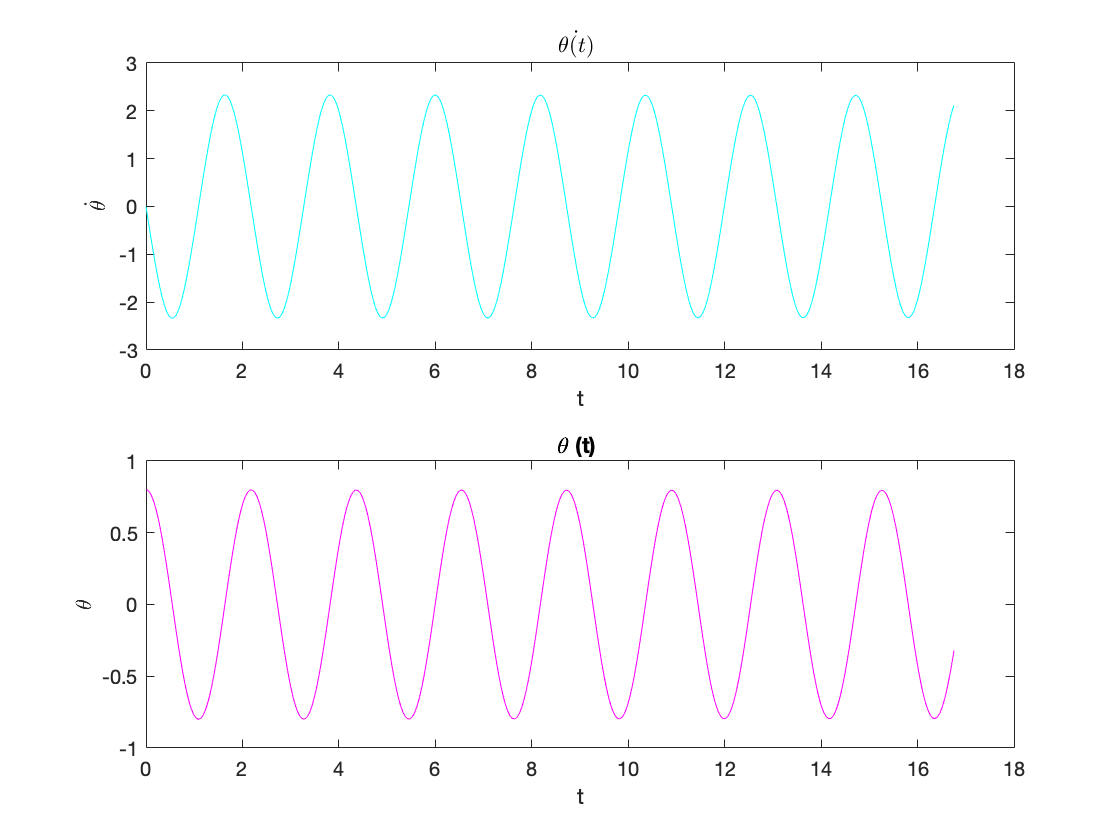

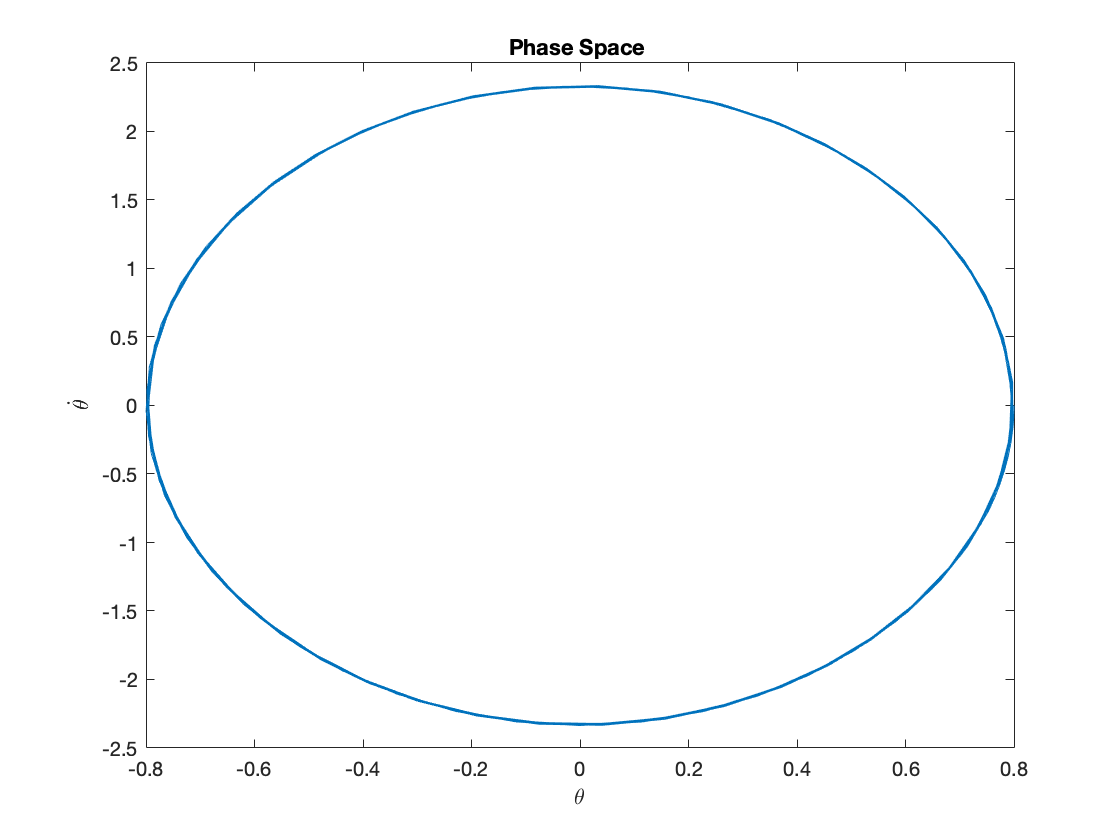

pendulum(1.09,0.8,0,1);

**Part b)**

**In all cases the behavior of theta and its derivative show an ocsillatory motion. **

**Period T deviates from its value in linear case only at very large angles (above 45 degree) and increases. **

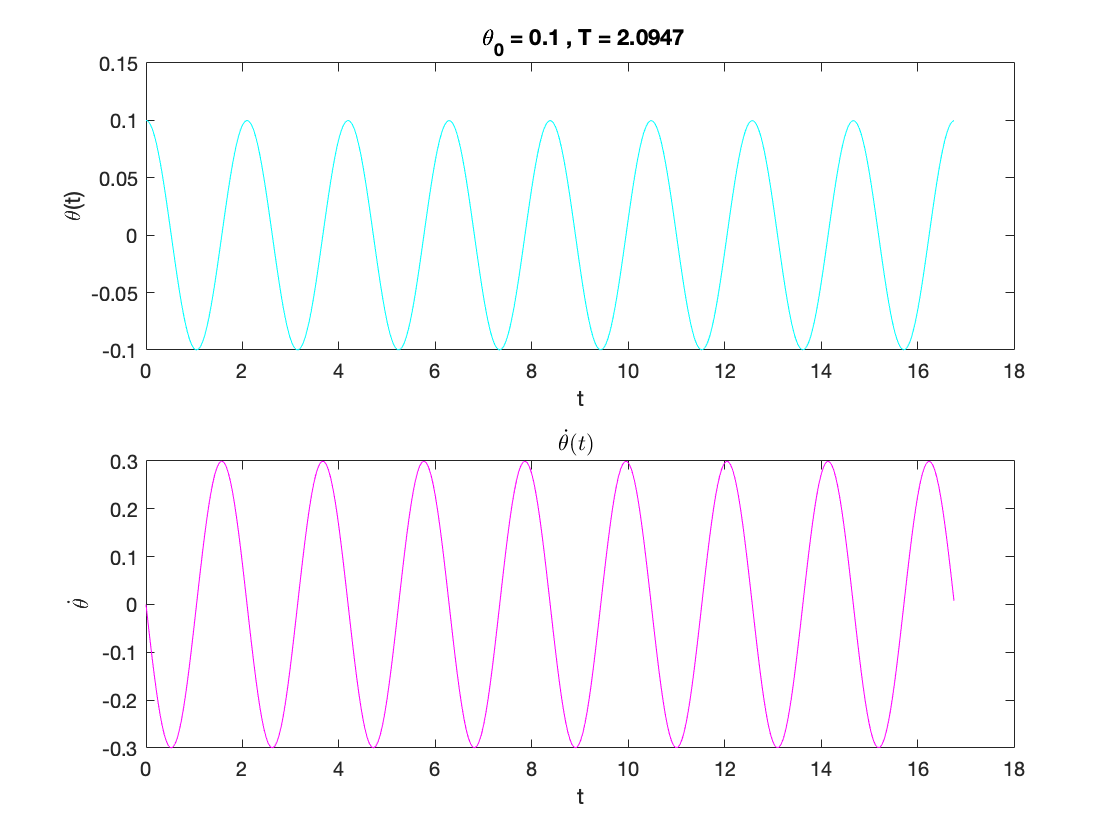

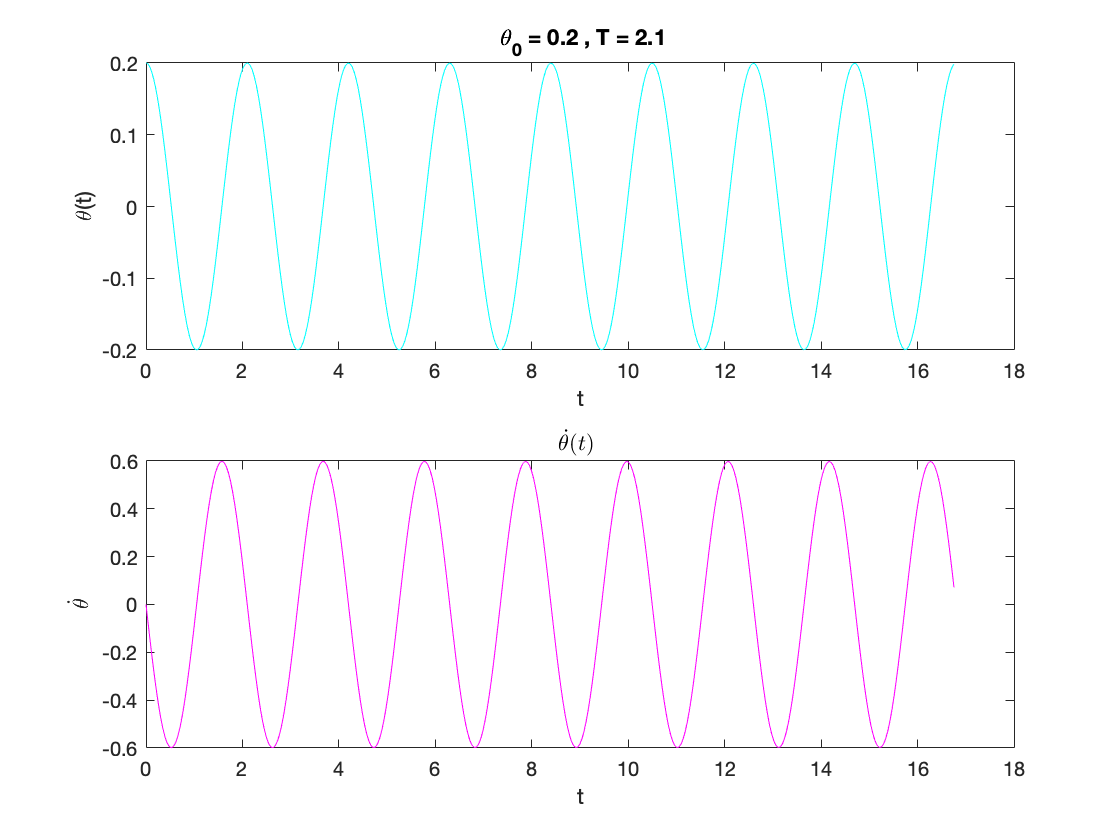

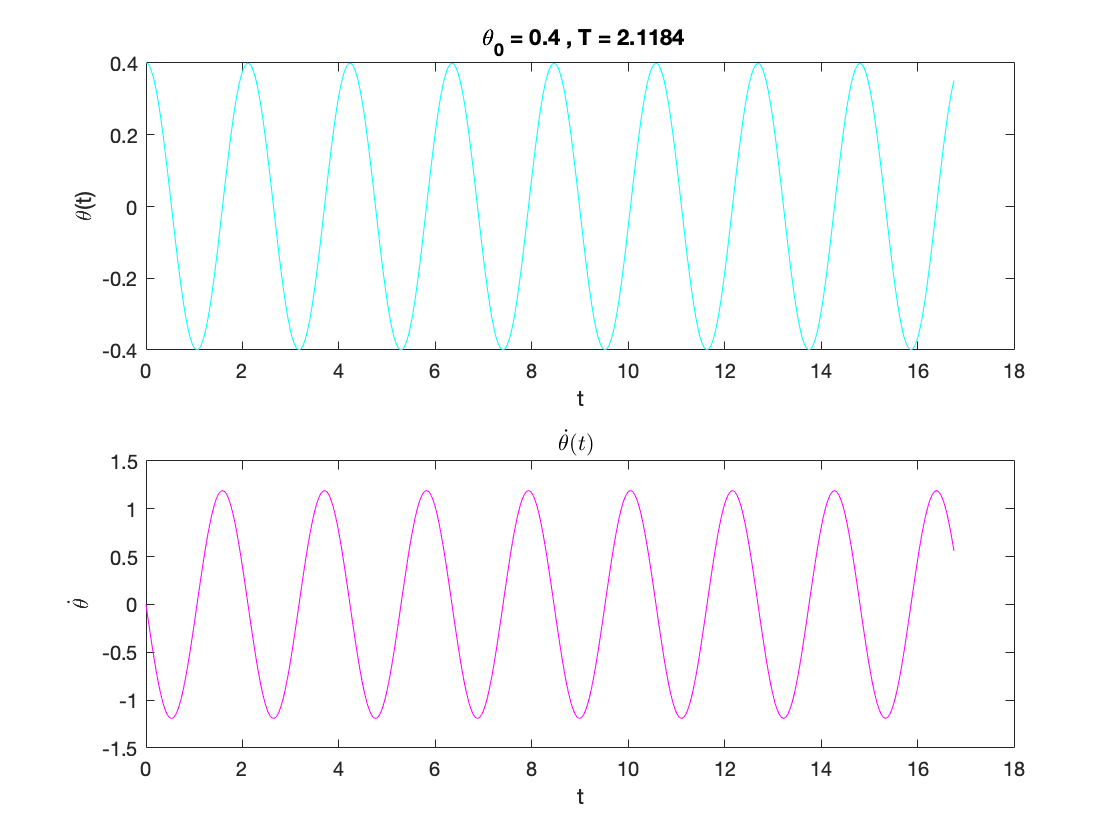

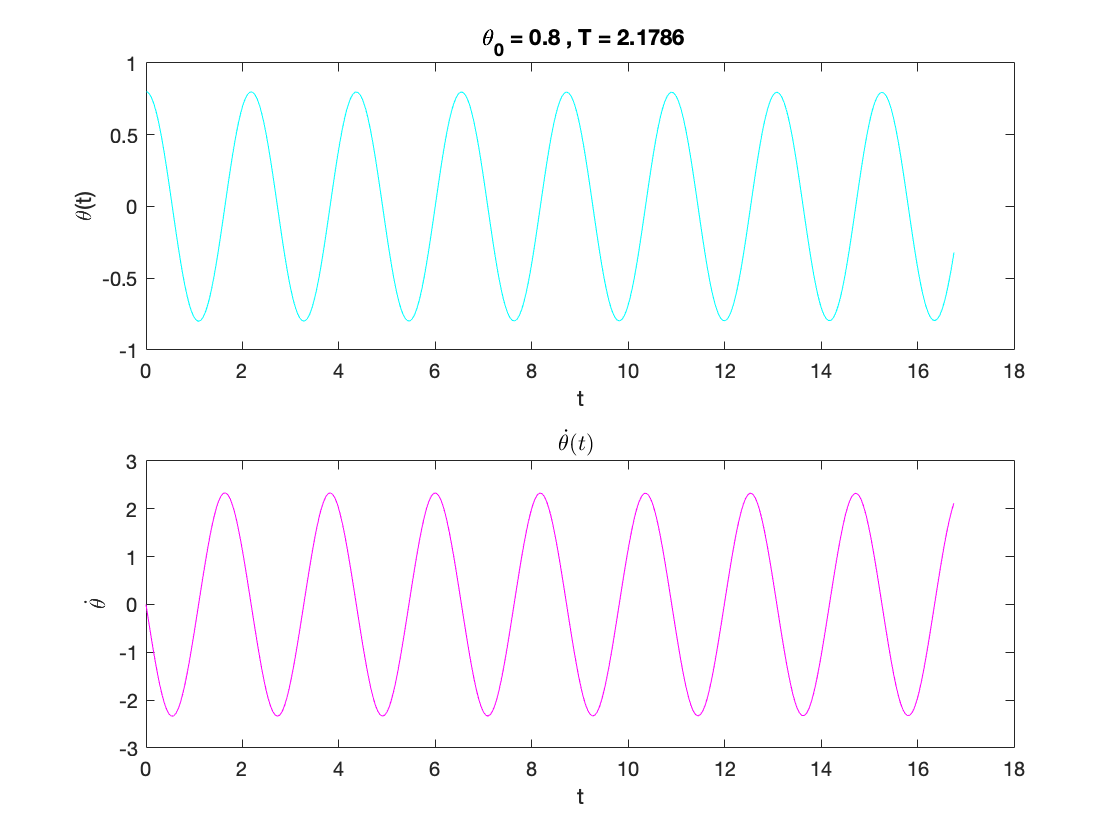

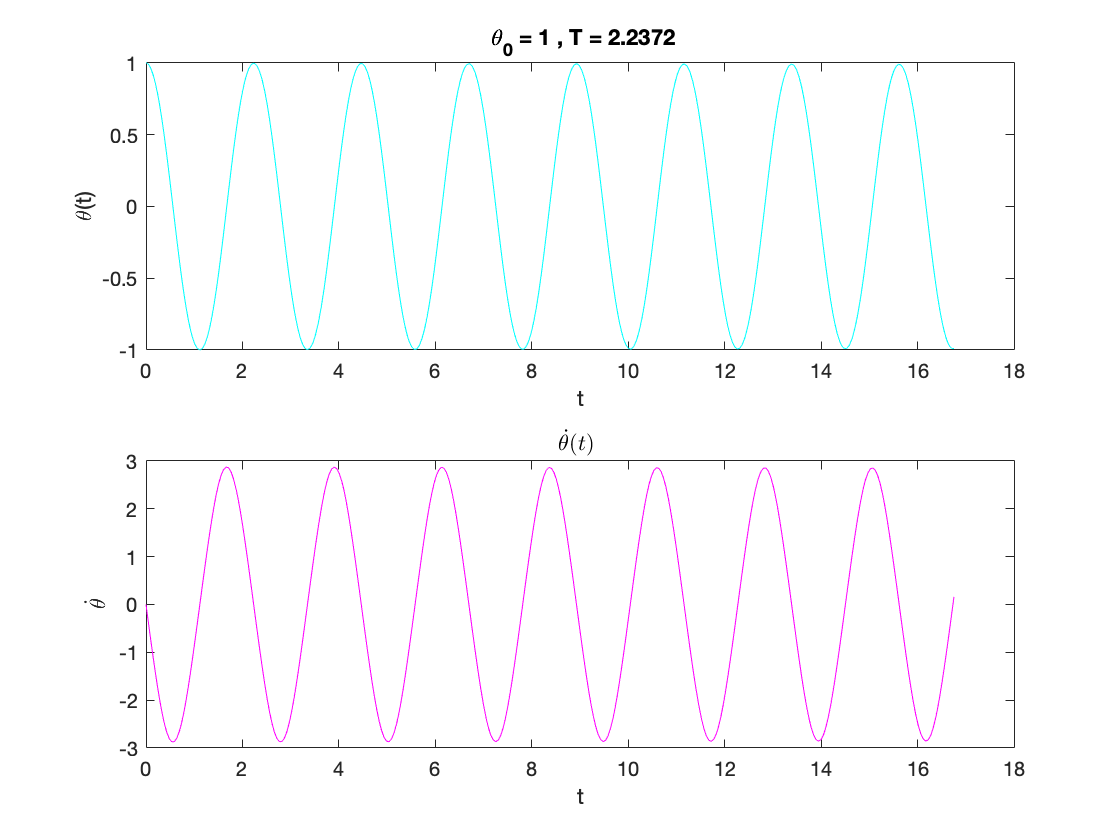




angle = [0.1 , 0.2 , 0.4, 0.8, 1.0];

T=zeros(1,length(angle));


for i=1:length(angle)
    [T(i), sol]=pendulum(1.09,angle(i),0,0);
    
    
    
    
    f1=figure ;
    
    subplot(2,1,1);
    plot(sol(:,1),sol(:,2),'c');
    title([' \theta_0 = ' num2str(angle(i)) ' , T = ' num2str(T(i))])
    xlabel('t')
    ylabel( '\theta(t)')
    
    
    subplot(2,1,2);
    plot(sol(:,1),sol(:,3), 'm');
    title('$\dot{\theta}(t)$ ', 'Interpreter','latex');
    xlabel('t');
    ylabel('$\dot{\theta}$', 'Interpreter','latex');
    
    
    
end  

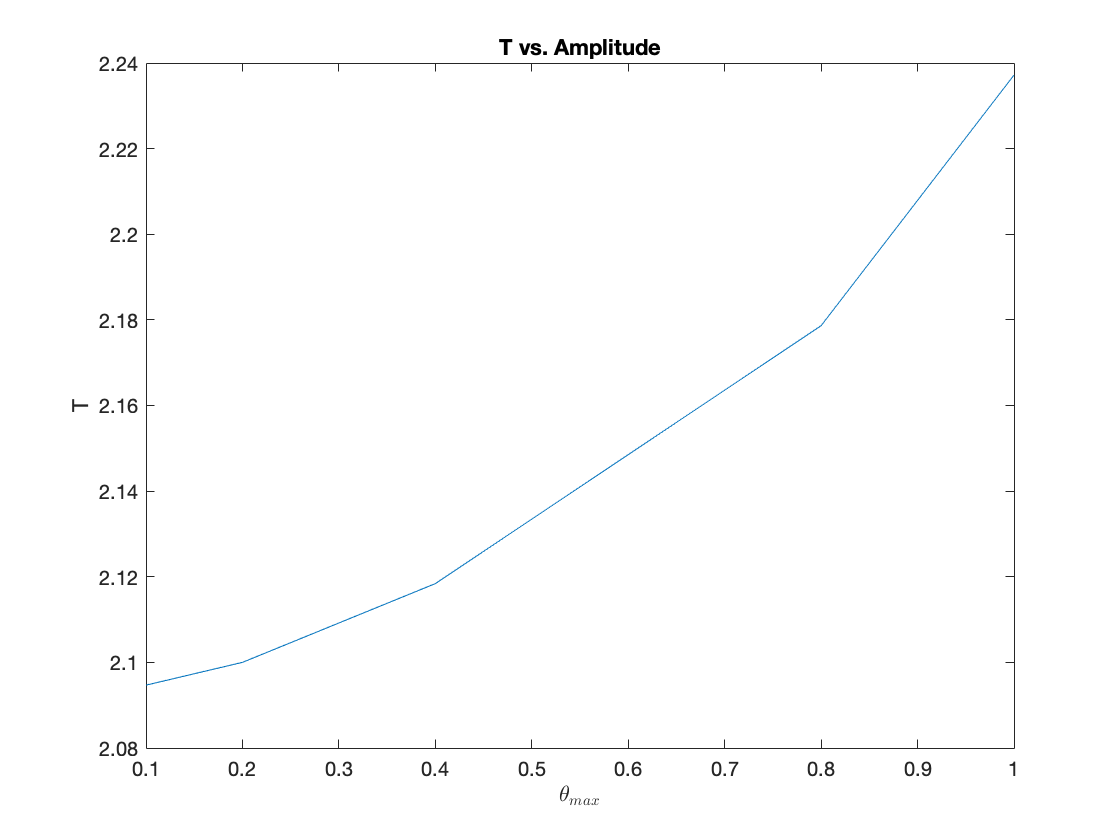


f2=figure;
plot (angle, T);
title ('T vs. Amplitude');
xlabel('$\theta_{max}$', 'Interpreter','latex');
ylabel('T');